Ntot = 512;
N = Ntot/4;
bcrit = 0.44069;
spin.pp = sign(0.5 - rand(N,N));           %randn dà numeri casuali tra -1 e 1, sign arrotonda a 1 se 
spin.dp = sign(0.5 - rand(N,N));        %positivo, -1 se negativo       
spin.dd = sign(0.5 - rand(N,N));          
spin.pd = sign(0.5 - rand(N,N));
%spin = sign(0.5 - rand(N,N));
J = 1;
beta = linspace(0.3,0.8,10);
Nbeta = length(beta);
%Applica algoritmo metropolis per una configurazione Ising 2D
sweeps = 1e4; %ripetizioni
therm = 1e2;
skip = 20;
Magmedia = zeros(1,sweeps/skip);
Mg = zeros(1,Nbeta);
dE = zeros(1,numel(spin));
E_media = zeros(1,sweeps/skip);
Energia = zeros(1,Nbeta);

hw = waitbar(0, "pregaiddio");
for cnt = 1:Nbeta
 b = beta(cnt);   
    
%             above = circshift(spin, [-1 0]);
%             below = circshift(spin, [+1 0]);
%             left = circshift(spin, [0 -1]);
%             right = circshift(spin, [0 1]);
%             vicini  = [above;                 %spin dei vicini
%                  left;      right;
%                        below;];
%             somma = above + below + left + right;
 
 
 for t = 1:therm
     
      %troviamo i vicini di pari-pari
      pp_vicini = spin.dp + circshift(spin.dp, [0 1]) + spin.pd + circshift(spin.pd, [1 0]);
      R = rand(N,N); 
      
      dE = 2*J.*spin.pp.*(pp_vicini); %variazione energia se inverto spin

      prob = exp(-dE*b);      %Probabilità di invertire spin
      
         accept = R < prob;
         spin.pp(accept) = -spin.pp(accept);
         
         
         %troviamo i vicini di dispari-pari
      dp_vicini = spin.pp + circshift(spin.pp, [0 1]) + spin.dd + circshift(spin.pd, [1 0]);
      R = rand(N,N); 
      
      dE = 2*J.*spin.dp.*(dp_vicini); %variazione energia se inverto spin

      prob = exp(-dE*b);      %Probabilità di invertire spin
      
         accept = R < prob;
         spin.dp(accept) = -spin.dp(accept);
         
         %troviamo i vicini di dispari-dispari
      dd_vicini = spin.pd + circshift(spin.pd, [0 1]) + spin.dp + circshift(spin.dp, [1 0]);
      R = rand(N,N); 
      
      dE = 2*J.*spin.dd.*(dd_vicini); %variazione energia se inverto spin

      prob = exp(-dE*b);      %Probabilità di invertire spin
      
         accept = R < prob;
         spin.dd(accept) = -spin.dd(accept);
         
         %troviamo i vicini di pari-dispari
      pd_vicini = spin.dd + circshift(spin.dd, [0 1]) + spin.pp + circshift(spin.pp, [1 0]);
      R = rand(N,N); 
      
      dE = 2*J.*spin.pd.*(pd_vicini); %variazione energia se inverto spin

      prob = exp(-dE*b);      %Probabilità di invertire spin
      
         accept = R < prob;
         spin.pd(accept) = -spin.pd(accept);
     
 end

   for s = 1:sweeps
       E_totale = 0.0;
            
        %troviamo i vicini di pari-pari
      pp_vicini = spin.dp + circshift(spin.dp, [0 1]) + spin.pd + circshift(spin.pd, [1 0]);
      R = rand(N,N); 
      
      dE = J.*spin.pp.*(pp_vicini); %variazione energia se inverto spin
      E_totale = E_totale + dE;

      prob = exp(-2*dE*b);      %Probabilità di invertire spin
      
         accept = R < prob;
         spin.pp(accept) = -spin.pp(accept);
         
         
         %troviamo i vicini di dispari-pari
      dp_vicini = spin.pp + circshift(spin.pp, [0 1]) + spin.dd + circshift(spin.dd, [1 0]);
      R = rand(N,N); 
      
      dE = J.*spin.dp.*(dp_vicini); %variazione energia se inverto spin
       E_totale = E_totale + dE;

      prob = exp(-2*dE*b);      %Probabilità di invertire spin
      
         accept = R < prob;
         spin.dp(accept) = -spin.dp(accept);
         
         %troviamo i vicini di dispari-dispari
      dd_vicini = spin.pd + circshift(spin.pd, [0 1]) + spin.dp + circshift(spin.dp, [1 0]);
      R = rand(N,N); 
      
      dE = J.*spin.dd.*(dd_vicini); %variazione energia se inverto spin
       E_totale = E_totale + dE;

      prob = exp(-2*dE*b);      %Probabilità di invertire spin
      
         accept = R < prob;
         spin.dd(accept) = -spin.dd(accept);
         
         %troviamo i vicini di pari-dispari
      pd_vicini = spin.dd + circshift(spin.dd, [0 1]) + spin.pp + circshift(spin.pp, [1 0]);
      R = rand(N,N); 
      
      dE = J.*spin.pd.*(pd_vicini); %variazione energia se inverto spin
       E_totale = E_totale + dE;

      prob = exp(-2*dE*b);      %Probabilità di invertire spin
      
         accept = R < prob;
         spin.pd(accept) = -spin.pd(accept);
         
         
         
         
         
         
         if rem(s,skip) == 0
             
         E_media(s/skip) = (-1/2).*sum(E_totale(:));         
         reticolo = cell2mat(struct2cell(spin));
   
         Magmedia(s/skip) = sum(reticolo(:))/(4*N^2);
         end
         
   end
   
   Mg(cnt) = abs(mean(Magmedia));
   Energia(cnt) = mean(E_media);
   
    waitbar(cnt/Nbeta);
end
 close(hw)
            
 
 
 
 fig1=figure; % Creiamo la prima figura
    set(fig1,'Windowstyle','docked') % Mettiamola 'docked'
    title(['Ising 2D con N = ',Ntot ,...
           ' e B = 0'],...
          'FontSize',16,'FontWeight','normal','FontAngle','it') 
    grid on 
    grid minor % grigla fitta
    hold on    
    errorbar(beta,Mg,errMg,...
             'Color','green','LineStyle','-','Marker','.',...
             'MarkerSize',8) % Plot della magnetizzazione media (B)
    %plot(x,Ons,'r-','LineWidth',2) % Plot della magnetizzazione scondo la formula esatta
    xline (bcrit, 'b-', 'LineWidth', 1);
    xlabel('\beta')
    ylabel('Magnetizzazione spontanea')          
    legend({'Simulazione','Previsione', '\beta critica'},'Location','NorthWest')

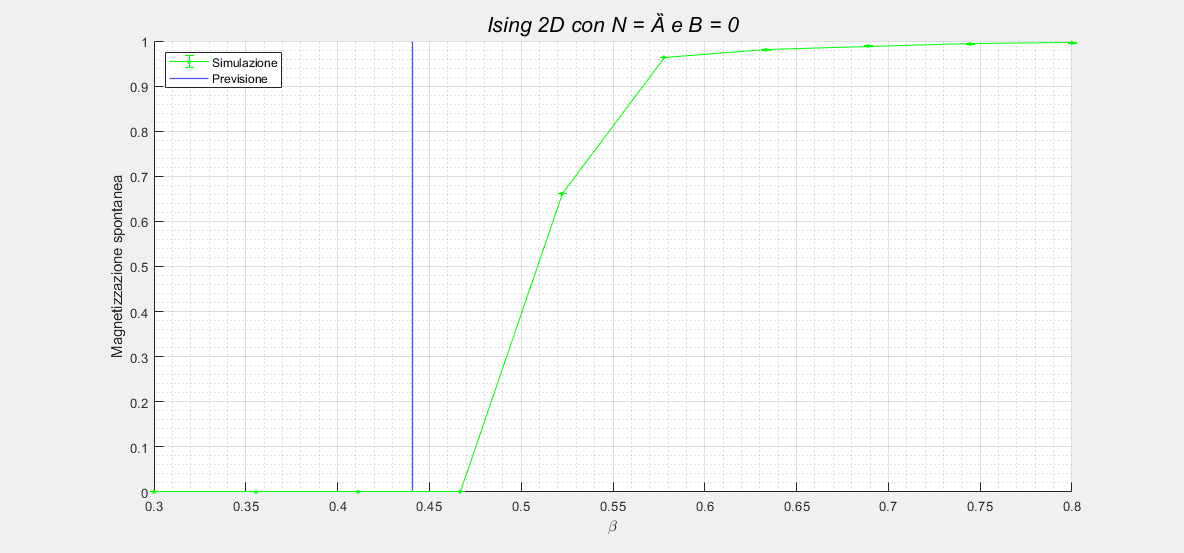

    hold off

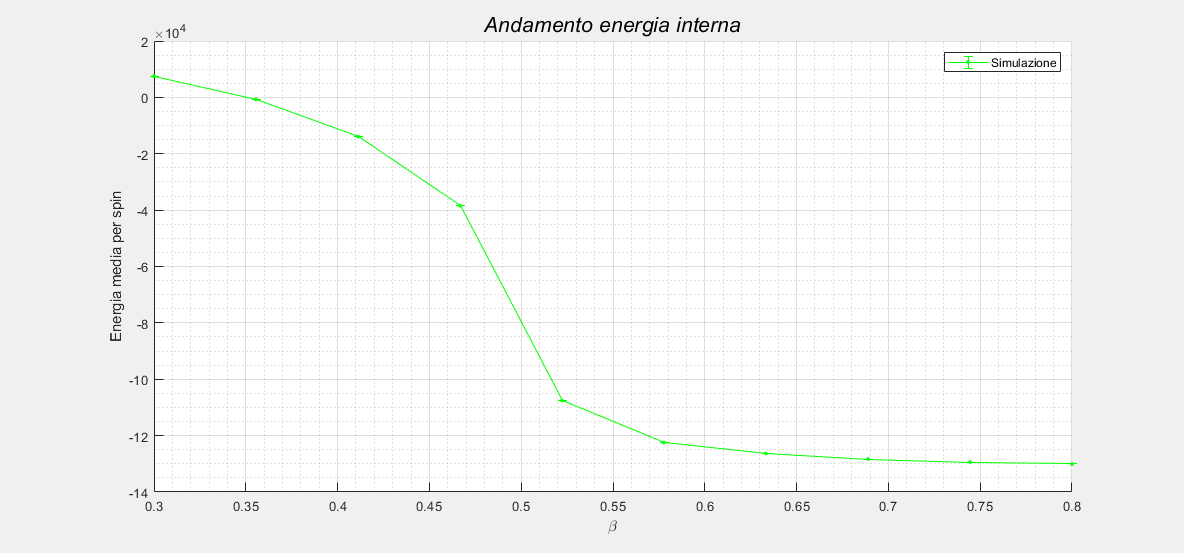

    
    fig2=figure;
    set(fig2,'Windowstyle','docked') % Mettiamola 'docked'
    title('Andamento energia interna',...
          'FontSize',16,'FontWeight','normal','FontAngle','it') 
    grid on 
    grid minor % grigla fitta
    hold on    
    errorbar(beta,Energia,errEn,...
             'Color','green','LineStyle','-','Marker','.',...
             'MarkerSize',8) % Plot dell'energia interna
    xlabel('\beta')
    ylabel('Energia media per spin')          
    legend({'Simulazione'},'Location','NorthEast')